N_Symbols = 4e0;
U_R = 0;       Sigma_R = sqrt(0.5);
U_I = 0;       Sigma_I = sqrt(0.5);

tones = 5;
h = zeros(tones,N_Symbols);

for i = 1:tones
h_R = randn([1 N_Symbols])*Sigma_R + U_R;
h_I = randn([1 N_Symbols])*Sigma_I + U_I;

h(i,:) = h_R + h_I*1j;
end
SIZE = 64;

SIZE = 64

h = [h; zeros(SIZE-tones,N_Symbols)];

% figure
% H_mag = histogram(abs(h),'Normalization','probability');
% title('PDF of Channel Magnitude')
% figure
% H_arg = histogram(angle(h),'Normalization','probability');
% title('PDF of Channel Phase')


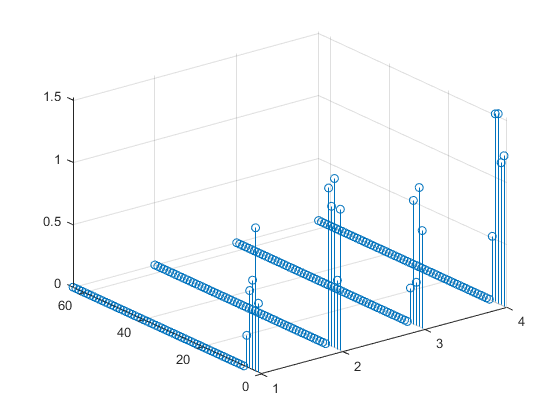

stem3(abs(h))

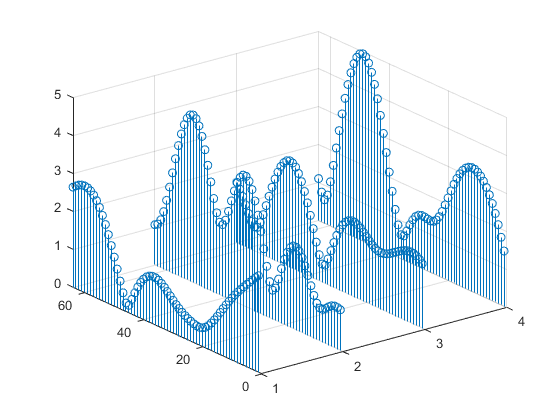

H = zeros(SIZE,N_Symbols);
for i = 1:N_Symbols
H(:,i) = fft(h(:,i));
end
stem3(abs(H))